# Retratos de fase (Phase portraits)

**NOTA: El siguiente código es la expliación paso a paso del funcionamiento de la función *****PhasePortrait.m***

## Presa - Depredador

Para realizar los retratos de fase, se utilizará el modelo clásico de presa depredador de Lotka-Volterra.


$$\dot{P}(t)= \alpha P(t) - \beta P(t)D(t)\\
\dot{D}(t)= \delta P(t) D(t) - \gamma D(t)$$


**Con los siguientes parámetros y estados:**

$P(t)$: Número de presas en el tiempo

$D(t)$: Depredadores en el tiempo

$\alpha$: Tasa instantánea de aumento de presas en ausencia de depredadores

$\beta$: Tasa de cacería de número de presas por depredador

$\delta$: Tasa de aumento de depredadores por presa cazada

$\gamma$: Tasa instantánea de disminución de depredadores en ausencia de presas

**1.** Primero se debe crear el modelo de interés, en este caso será el modelo de presa depredador clásico de Lotka-Volterra 

Para esto creamos una función con los parámetros y ecuaciones incluidas en su interior (en este caso *PresaDepredador.m *en la carpeta *funciones*).

addpath("funciones")

f = @PresaDepredador; %modelo creado a partir de la funcion PresaDepredador

**Nota:** También, si no se desea crear un archivo con el sistema de ecuaciones, es posible utilizar *Handle functions* en Matlba. Con estas podemos definir funciones de manera directa en el script, la ventaja es que no es necesario abrir un archivo para cambiar el valor de los parámetros.

**2.** Posteriormente se definen los parámetros para realizar el retrato de fase

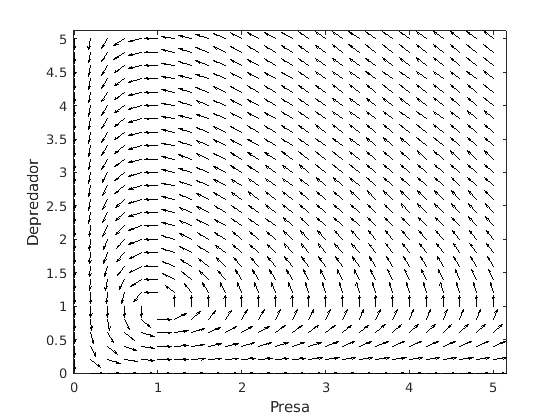

intervalX1 = 0 : 0.2 : 5; % intervalo para estado 1 (x1)
intervalX2 = 0 : 0.2 : 5; % intervalo para estado 2 (x2)

figure
vectfieldn(f, intervalX1, intervalX2)
xlabel("Presa")
ylabel("Depredador")

**3. **Graficar algunas trayectorias dejando fija la condición inicial del estado x1 y variando la condición inicial del estado x2

Los circulos verdes representan las condiciones iniciales y los cuadros negros las condiciones finales

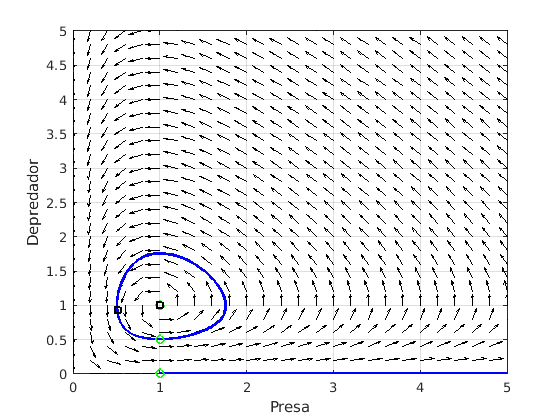

figure
vectfieldn(f, intervalX1, intervalX2)  
hold on
ydom = linspace(0, 50, 1000);
X10 = 1;            %Condicion inicial para las presas

for X20 = [0 0.5 1] %multiples condiciones iniciales para los depredadores
    
    [~, ysim] = ode45(@(t,Y) f(t,Y), ydom, [X10, X20]);
    plot(ysim(:, 1), ysim(:, 2), 'b', 'LineWidth', 2)                   %Trayectoria de estado
    plot(ysim(1, 1), ysim(1, 2),'o', 'color', 'g', 'LineWidth',2)       %Punto inicial
    plot(ysim(end, 1), ysim(end, 2),'s', 'color', 'k', 'LineWidth',2)   %Punto final
    
end

xlim([intervalX1(1) intervalX1(end)])
ylim([intervalX2(1) intervalX2(end)])
grid on
xlabel("Presa")
ylabel("Depredador")

Ahora, las simulaciones de cada variable en el tiempo de acuerdo a las condiciones iniciales anteriormente descritas se presentan a continuación:

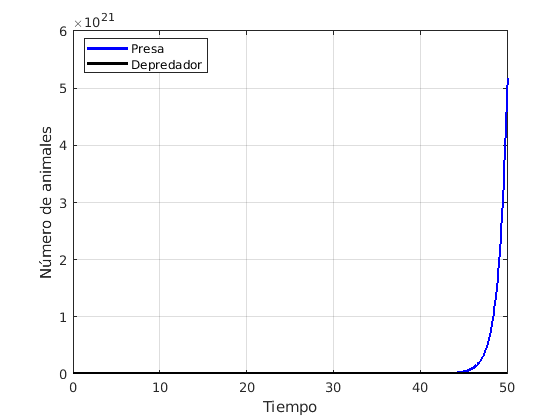

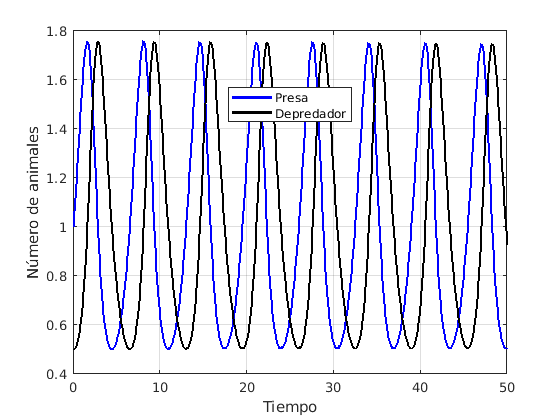

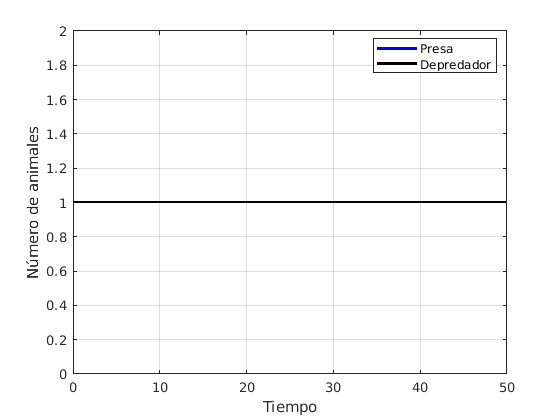

for X20 = [0 0.5 1]
    figure
    
    [tsim,ysim] = ode45(@(t,Y) f(t,Y), ydom, [X10, X20]);
    plot(tsim, ysim(:, 1), 'b', 'LineWidth', 2)
    hold on
    plot(tsim, ysim(:, 2), 'k', 'LineWidth', 2)  
    
    xlabel('Tiempo')
    ylabel('Número de animales')
    legend('Presa', 'Depredador', 'Location', 'best')
    grid on
end

# Retratos de fase para modelos de 3 estados 

En este caso se utiliza como ejemplo el modelo de [Lorenz](https://mathworld.wolfram.com/LorenzAttractor.html) de 3 estados:


$$\dot{X} = \delta (Y - X)\\
\dot{Y} = X(\rho - Z) - Y\\
\dot{Z} = XY - \beta Z$$


**1. **Creación del modelo como una handle function

%valor de los parámetros del modelo
params = [6  %delta
          23 %rho
          10 %beta
          ];
%Handle function (modelo)
%el vector x representa las variables de estado
%el modelo se escribe de manera vectorial
f = @(t,x) [
    params(1)*(x(2)-x(1));
    x(1)*(params(2) - x(3)) - x(2);
    x(1)*x(2) - params(3)*x(3);
    ];

**2.** Se definen los parámetros para realizar el retrato de fase

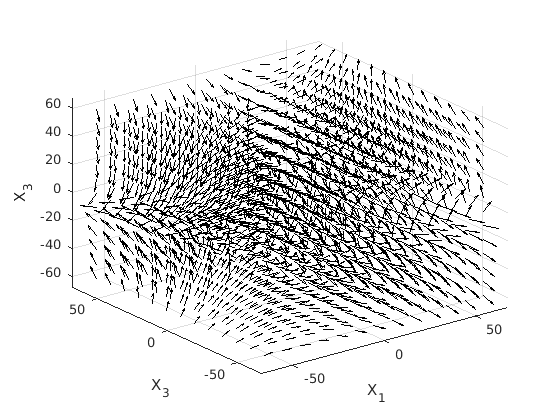

resolution = 10;
Min = -60;
Max = 60;

intervalX1 = Min : resolution : Max; % intervalo para estado 1 (x1)
intervalX2 = Min : resolution : Max; % intervalo para estado 2 (x2)
intervalX3 = Min : resolution : Max; % intervalo para estado 2 (x2)

figure
vectfieldn3(f, intervalX1, intervalX2, intervalX3)
xlabel("X_1")
ylabel("X_2")
ylabel("X_3")

**3.** Graficar algunas trayectorias dejando fija la condiciones iniciales de X1 y X3 y variando la condición inicial del estado X2

Los circulos verdes representan las condiciones iniciales y los cuadros negros las condiciones finales

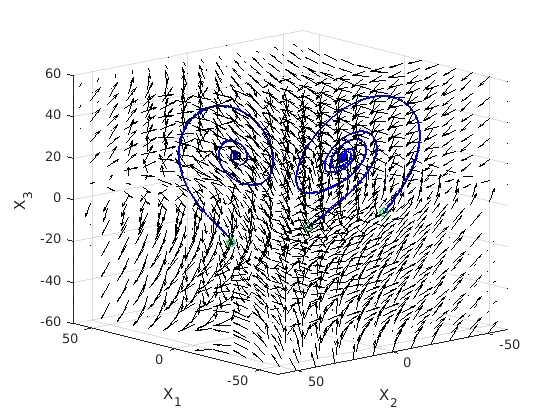

figure
vectfieldn3(f, intervalX1, intervalX2, intervalX3)  
hold on
ydom = linspace(0, 4, 100000);
X10 = -10;            %Condicion inicial X_1
X30 = -10;            %Condicion inicial X_3

for X20 = [-40 0 40] %multiples condiciones iniciales para X_2
    [~, ysim] = ode45(@(t,Y) f(t,Y), ydom, [X10, X20, X30]);
    plot3(ysim(:, 1), ysim(:, 2), ysim(:, 3), 'b', 'LineWidth', 2)                      %Trayectoria de estado
    plot3(ysim(1, 1), ysim(1, 2), ysim(1, 3),'o', 'color', 'g', 'LineWidth',2)          %Punto inicial
    plot3(ysim(end, 1), ysim(end, 2), ysim(end, 3), 's', 'color', 'k', 'LineWidth',2)   %Punto final
end

xlim([intervalX1(1) intervalX1(end)])
ylim([intervalX2(1) intervalX2(end)])
zlim([intervalX3(1) intervalX3(end)])

grid on
xlabel("X_1")
ylabel("X_2")
zlabel("X_3")
view([-131.7 15.1])

Ahora, las simulaciones de cada variable en el tiempo de acuerdo a las condiciones iniciales anteriormente descritas se presentan a continuación:

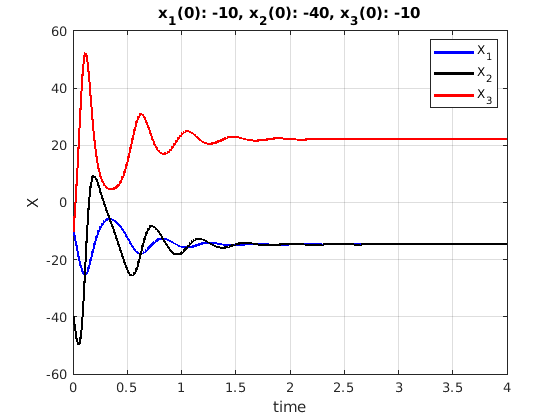

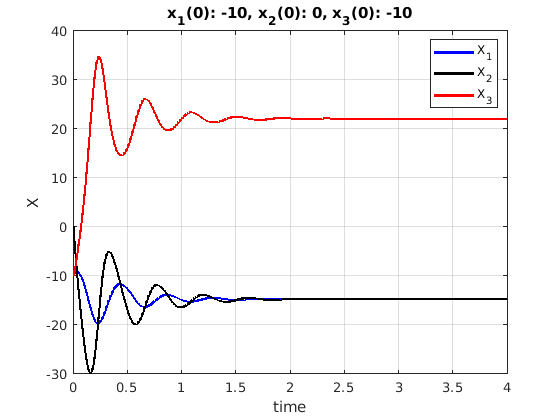

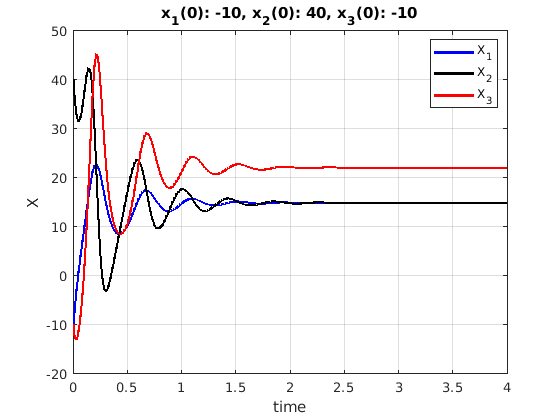

X10 = -10;            %Condicion inicial para las presas
X30 = -10; 
for X20 = [-40 0 40]    
    figure
    
    [tsim,ysim] = ode45(@(t,Y) f(t,Y), ydom, [X10, X20, X30]);
    plot(tsim, ysim(:, 1), 'b', 'LineWidth', 2)
    hold on
    plot(tsim, ysim(:, 2), 'k', 'LineWidth', 2)  
    plot(tsim, ysim(:, 3), 'r', 'LineWidth', 2)  
    
    xlabel('time')
    ylabel('X')
    legend("X_1", "X_2", "X_3", 'Location', 'best')
    title("x_1(0): " + num2str(X10) + ", x_2(0): " + num2str(X20) + ", x_3(0): " + num2str(X30))
    grid on
end